# *ME 599F - Robotics, Vision, Mechtronics for Manufacturing*

## Lab 3: Aditya Mahendru, Keeranat Kolatat, Munzir Abdulmajid

**Q1**

[vision-based trajectory planning] Suppose that a small whiteboard (0.2 meter long, 0.1 meter wide) is put near the Puma robot, with its working surface facing up. The robot is holding a marker pen. There is a calibrated camera fixed to the robot end-effector. Your goal is to calculate a moving trajectory, such that the robot can draw a rectangular shape on the whiteboard: 

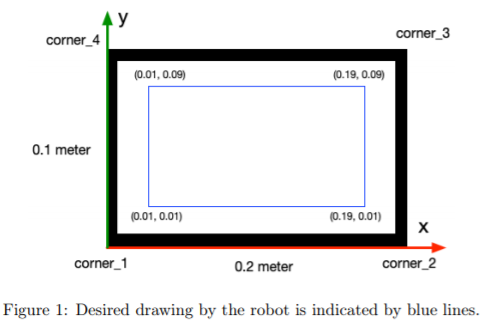

**The position of the whiteboard with respect to the robot base is unknown.** The robot is initially at joint position *q_start*. At this robot position, we took a picture of the whiteboard using the calibrated camera. After some imaging processing, we get the image coordinates *imgPoints* (4 × 2 matrix) of the four corners of the whiteboard (in the order of corner_1, corner_2, corner_3, corner_4). To approach the problem, we consider five coordinate systems in this problem:

- Robot base {B}: coordinate system attached to the robot base. 

- TCP {T}: coordinate system attached to the robot end-effector. 

- Camera {C}: coordinate system attached to the camera. The origin defined by the camera projection model. 

- Pen tip {P}: coordinate system attached to the pen tip. The origin is located at the tip, z-axis pointing towards the pen tip. 

- Whiteboard {W}: coordinate system attached to the whiteboard, defined in Figure 1.

The constant pose from {T} to {C} and from {T} to {P} is known. The pose from {B} to {T} can be calculated by robot forward kinematics. The relative pose between {C} and {W} can be estimated from image given by the calibrated camera.

Complete the MATLAB script traj_generation.m. We have provided all known variables in the code. You need to generate the trajectory based on the given information. Each waypoint in the trajectory should be a pose of TCP with respect to the robot base.

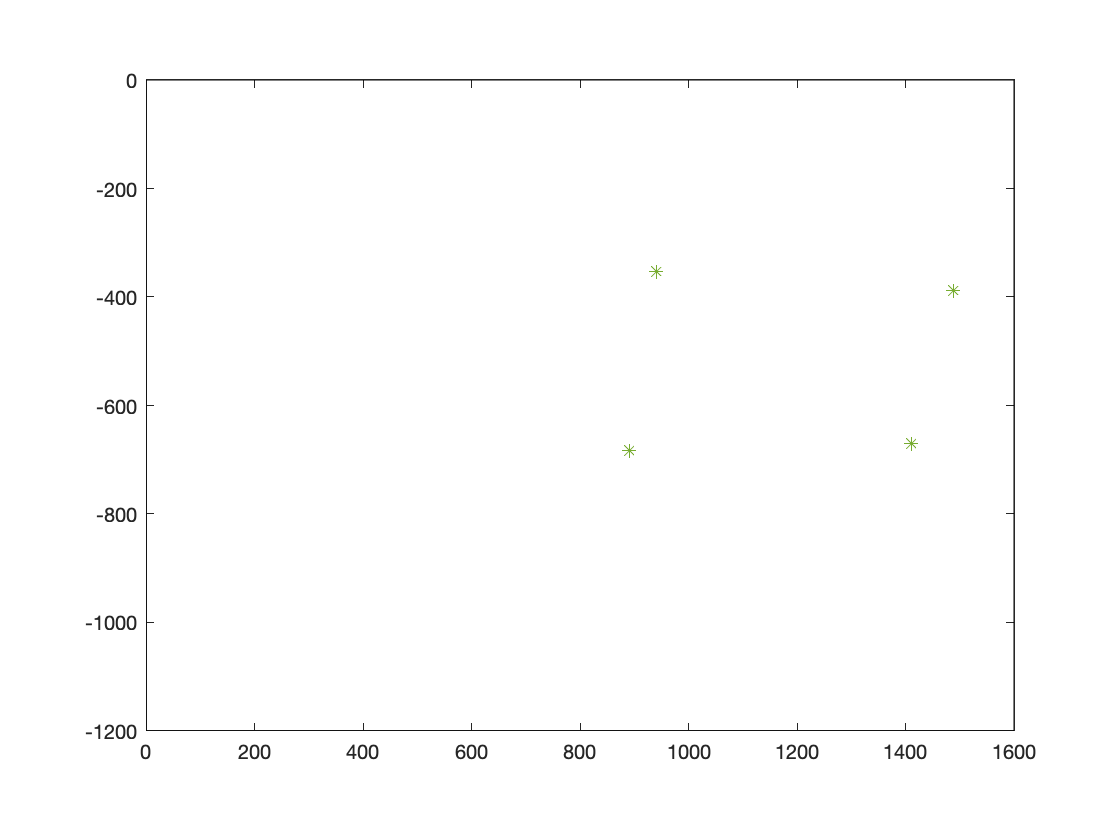

clear all;
close all;
clc;

% initial joint angles for the robot.
q_start = [3.36779, 1.1432, 0.2242, -0.3641, 1.5230, 0.1472];

% image coordinates of the projected feature points
% this is generated by simulation (assuming zero error in feature
% extraction step)
mdl_puma560;
robot = robotWithPen(p560);
imgPoints = robot.project(robot.robot.fkine(q_start))';

% visualize imgPoints
robot.plotImgPoint(imgPoints')

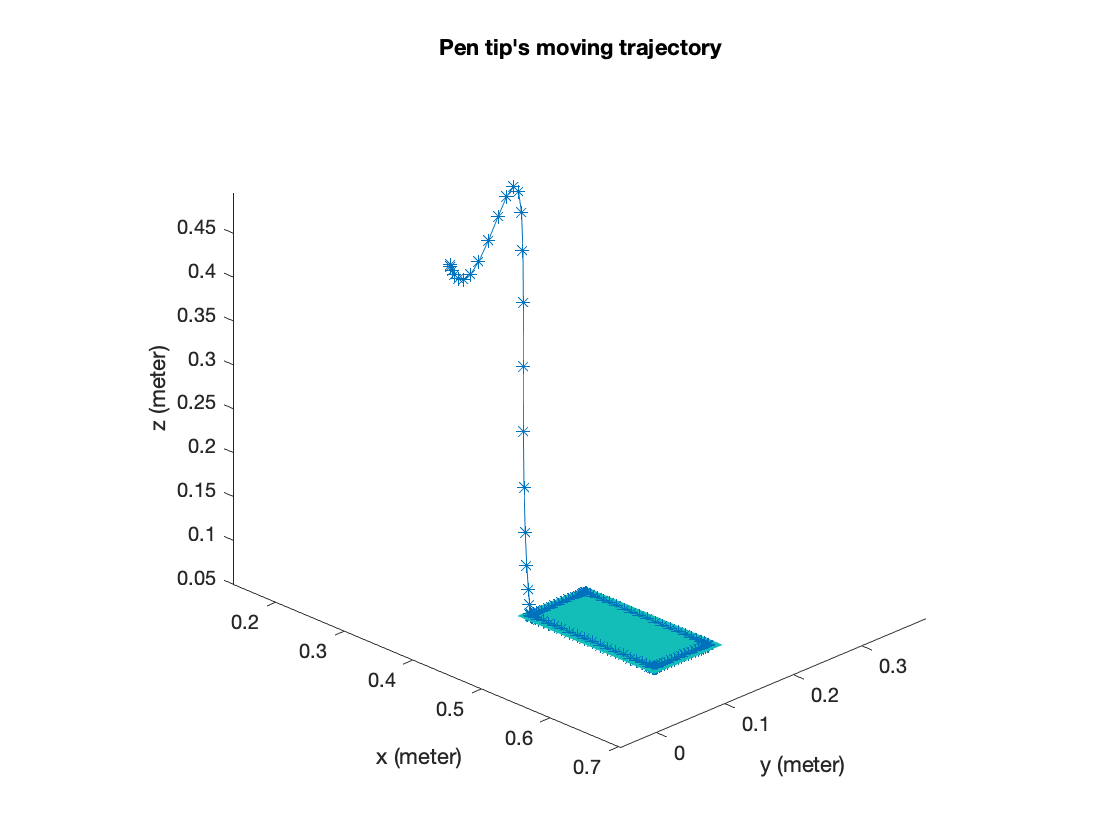

% pose of camera w.r.t TCP
tcp2camera = robot.tcp2camera_pose; % T xi C

% pose of pen tip w.r.t TCP
tcp2pen = robot.tcp2pentip_pose; % T xi P

% camera parameter (cameraIntrinsics object)
K = robot.camera_matrix;
param = cameraIntrinsics([K(1,1), K(2,2)], [K(1,3), K(2,3)], robot.img_size);

% create trajectory.
% --- your code start from here. ---
% you should create 'traj' variable that contains the moving trajectory.
% 'traj' should defines the poses of TCP w.r.t the robot base. (T xi B)
% 'traj' should be of type 1xN SE3, where N is the number of waypoints in
% your trajecotry.

whiteboardEdges= [0, 0, 0; 0.2, 0, 0; 0.2, 0.1, 0; 0, 0.1, 0];
rectangle = [0.01, 0.01, 0; 0.19, 0.01, 0; 0.19, 0.09, 0; 0.01, 0.09, 0];

[whiteboardOrientation,whiteboardLocation] = estimateWorldCameraPose(imgPoints, whiteboardEdges, param);

% Homogeneous Matrix
base2tcp=p560.fkine(q_start); 
base2camera=base2tcp * tcp2camera; 
base2pen = base2tcp * tcp2pen; 
whiteboard2camera = zeros(4,4);
whiteboard2camera(1:3, 1:3) = whiteboardOrientation';
whiteboard2camera(:,4) = [whiteboardLocation';1]; 
whiteboard2camera = SE3(whiteboard2camera);
base2whiteboard = base2camera * inv(whiteboard2camera); 
camera2pen = tcp2pen*inv(tcp2camera); 

% Points for the rectangle
corner_1 = base2whiteboard*SE3(rectangle(1,:))*SE3.Rx(pi)*inv(tcp2pen);
corner_2 = base2whiteboard*SE3(rectangle(2,:))*SE3.Rx(pi)*inv(tcp2pen);
corner_3 = base2whiteboard*SE3(rectangle(3,:))*SE3.Rx(pi)*inv(tcp2pen);
corner_4 = base2whiteboard*SE3(rectangle(4,:))*SE3.Rx(pi)*inv(tcp2pen);
    
% Trajectories
corner0_corner1 = ctraj(base2tcp,corner_1,25);
corner1_corner2 = ctraj(corner_1,corner_2,25);
corner2_corner3 = ctraj(corner_2,corner_3,25);
corner3_corner4 = ctraj(corner_3,corner_4,25);
corner4_corner1 = ctraj(corner_4,corner_1,25);

% traj = [start_2_corner1];
traj = [corner0_corner1,corner1_corner2,corner2_corner3,corner3_corner4,corner4_corner1];

%% plot trajectory
robot.plotTrajectory(traj)

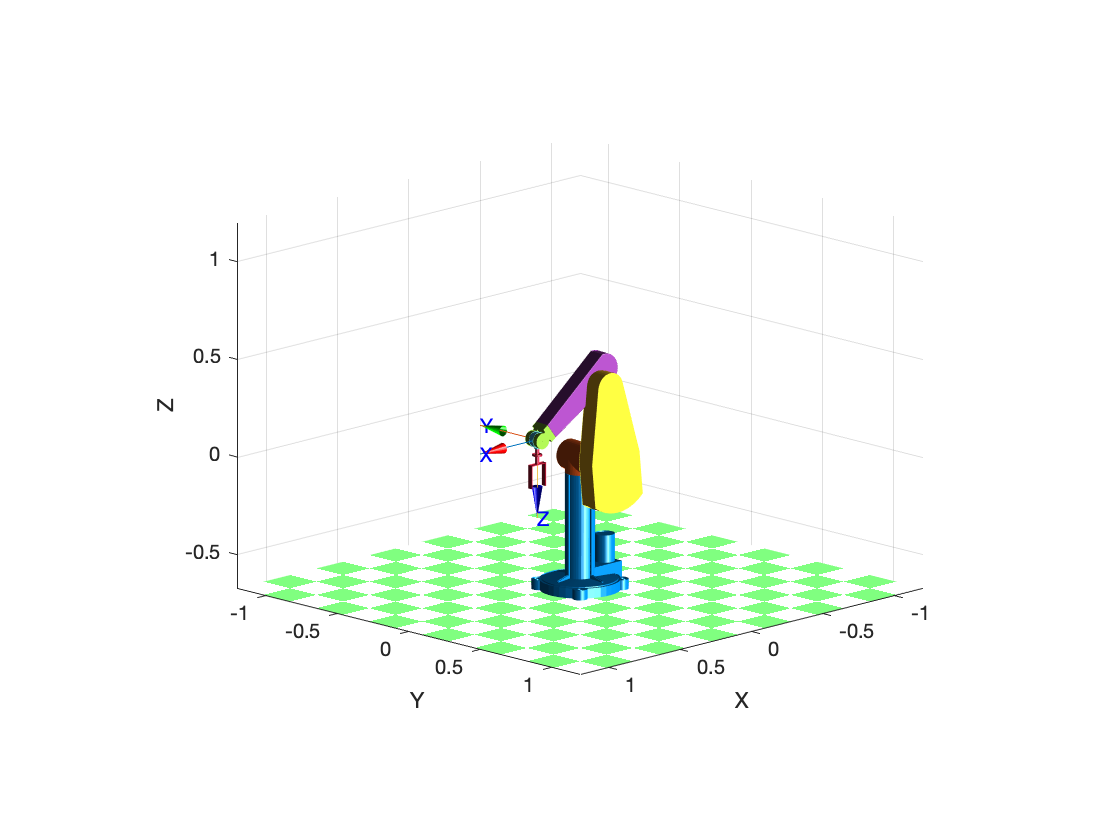

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


%% visualize trajectory
figure;
q_list = robot.robot.ikine6s(traj);
robot.robot.plot3d(q_list)

`------`